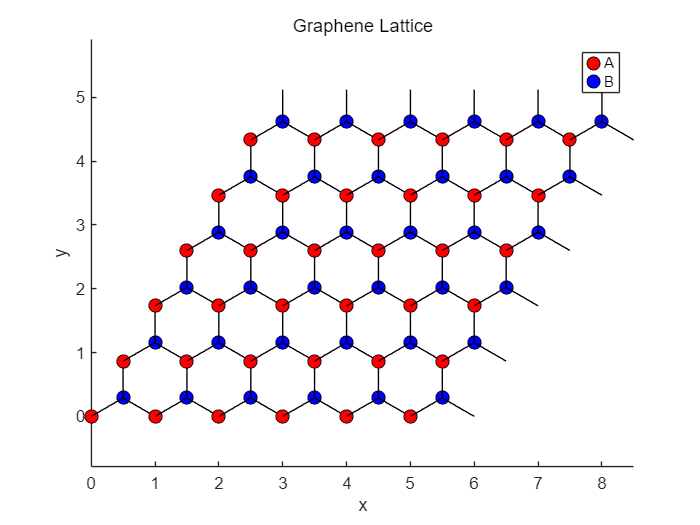

% % Example of usage:
Nx = 5; % Number of unit cells in x-direction
Ny = 5; % Number of unit cells in y-direction
% 
% plot_graphene_lattice(Nx, Ny);
% 
tic;
% Example of usage:
radius = 5; % Radius of the circular region
plot_graphene_lattice(Nx, Ny)

% rotate
% t = hgtransform('parent',gca);
% set(p,'Parent',t)
% Txy = makehgtform('zrotate',[1,1]);     % define a transform matrix
% set(t,"Matrix",Txy)

% hold on

% rotate(p,[0,0,1],30)

错误使用 rotate (第 29 行)
H 必须仅包含坐标区子级。

% plot(p.XData,p.YData)
% hold on
% plot_graphene_lattice_circle(radius,0.1);



toc;

% 
% % Example of usage:
% num_layers = 3; % Number of hexagonal layers
% plot_graphene_hexagonal_layers(num_layers);
% 





function plot_graphene_lattice(Nx, Ny)
    % Function to plot the 2D graphene lattice
    % Nx: Number of unit cells in the x-direction
    % Ny: Number of unit cells in the y-direction

    % Define lattice vectors for graphene
    a1 = [1, 0]; % Lattice vector in x-direction
    a2 = [1/2, sqrt(3)/2]; % Lattice vector in y-direction

    % Define atom positions within a unit cell
    atom_A = [0, 0]; % Position of atom A
    atom_B = [0.5, sqrt(3)/6]; % Position of atom B

    % Create figure
    p = figure;
    hold on;
    axis equal;
    xlabel('x');
    ylabel('y');
    title('Graphene Lattice');

    % Loop over each unit cell
    for x = 0:Nx
        for y = 0:Ny
            % Calculate positions of atoms in the current unit cell
            R = x * a1 + y * a2; % Unit cell position
            pos_A = R + atom_A;
            pos_B = R + atom_B;

            % Plot atoms
            p = plot(pos_A(1), pos_A(2), 'ko', 'MarkerFaceColor', 'r', 'MarkerSize', 8); % Atom A
            p = plot(pos_B(1), pos_B(2), 'ko', 'MarkerFaceColor', 'b', 'MarkerSize', 8); % Atom B

            % Plot bonds (nearest neighbors)
            p = plot([pos_A(1), pos_B(1)], [pos_A(2), pos_B(2)], 'k-'); % Bond A-B
            p = plot([pos_B(1), pos_A(1) + a1(1)], [pos_B(2), pos_A(2)], 'k-'); % Bond A-B (right)
            p = plot([pos_B(1), pos_B(1)], [pos_B(2), pos_B(2)+a2(1)], 'k-'); % Bond A-B (up)
        end
    end

    % % Set axis limits
    % xlim([-0.5, Nx] * a1(1));
    % ylim([-0.5, Ny] * a2(2));

    hold off;
    legend({'A','B'})
end




function p = plot_graphene_lattice_circle(radius,atomsize)
    % Function to plot the 2D graphene lattice within a circular region
    % radius: Radius of the circular region

    % Define lattice vectors for graphene
    a1 = [1, 0]; % Lattice vector in x-direction
    a2 = [0.5, sqrt(3)/2]; % Lattice vector in y-direction

    % Define atom positions within a unit cell
    atom_A = [0, 0]; % Position of atom A
    atom_B = [0.5, sqrt(3)/6]; % Position of atom B

    % Create figure
    p = figure;
    hold on;
    axis equal;
    xlabel('x');
    ylabel('y');
    title('Graphene Lattice in Circular Region');

    % Calculate maximum number of unit cells needed to cover the circle
    max_cells = ceil(2 * radius);

    % Loop over each unit cell
    for x = -max_cells:max_cells
        for y = -max_cells:max_cells
            % Calculate positions of atoms in the current unit cell
            R = x * a1 + y * a2; % Unit cell position
            pos_A = R + atom_A;
            pos_B = R + atom_B;

            % Check if the atom positions are within the circular region
            if norm(pos_A) < radius
                plot(pos_A(1), pos_A(2), 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', atomsize); % Atom A
            end
            if norm(pos_B) < radius
                plot(pos_B(1), pos_B(2), 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', atomsize); % Atom B
            end

            % Plot bonds (nearest neighbors) within the circle
            if norm(pos_A) <= radius && norm(pos_B) <= radius
                plot([pos_A(1), pos_B(1)], [pos_A(2), pos_B(2)], 'k-'); % Bond A-B
            end
            if norm(pos_A) <= radius && norm(pos_B + a1) <= radius
                plot([pos_B(1), pos_A(1) + a1(1)], [pos_B(2), pos_A(2)], 'k-'); % Bond A-B (right)
            end
            if norm(pos_A) <= radius && norm(pos_B + a2) <= radius
                plot([pos_B(1), pos_B(1)], [pos_B(2), pos_B(2)+a2(1)], 'k-'); % Bond A-B (up)
            end
        end
    end

    % Plot circle boundary
    % theta = linspace(0, 2*pi, 100);
    % plot(radius * cos(theta), radius * sin(theta), 'k--');
    legend({'A','B'})
    hold off;
end




function plot_graphene_hexagonal_layers(num_layers)
    % Function to plot the 2D graphene lattice with a given number of hexagonal layers
    % num_layers: Number of hexagonal layers extending from the center

    % Define lattice vectors for graphene
    a1 = [1, 0]; % Lattice vector in x-direction
    a2 = [0.5, sqrt(3)/2]; % Lattice vector in y-direction

    % Define atom positions within a unit cell
    atom_A = [0, 0]; % Position of atom A
    atom_B = [0.5, sqrt(3)/6]; % Position of atom B

    % Create figure
    % figure;
    hold on;
    axis equal;
    xlabel('x');
    ylabel('y');
    title(['Graphene Lattice with ', num2str(num_layers), ' Hexagonal Layers']);

    % Loop over each unit cell within the hexagonal layers
    for x = -num_layers:num_layers
        for y = -num_layers:num_layers
            % Calculate positions of atoms in the current unit cell
            R = x * a1 + y * a2; % Unit cell position
            pos_A = R + atom_A;
            pos_B = R + atom_B;

            % Check if the unit cell is within the hexagonal layers
            if abs(x + y) <= num_layers
                % Plot atoms
                plot(pos_A(1), pos_A(2), 'ko', 'MarkerFaceColor', 'r', 'MarkerSize', 8); % Atom A
                plot(pos_B(1), pos_B(2), 'ko', 'MarkerFaceColor', 'b', 'MarkerSize', 8); % Atom B

            % Plot bonds (nearest neighbors)
            plot([pos_A(1), pos_B(1)], [pos_A(2), pos_B(2)], 'k-'); % Bond A-B
            plot([pos_B(1), pos_A(1) + a1(1)], [pos_B(2), pos_A(2)], 'k-'); % Bond A-B (right)
            plot([pos_B(1), pos_B(1)], [pos_B(2), pos_B(2)+a2(1)], 'k-'); % Bond A-B (up)
            end
        end
    end

    hold off;
end

